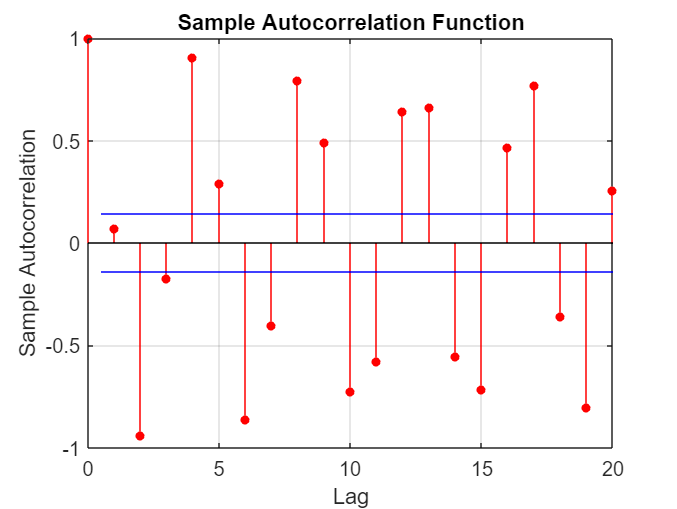

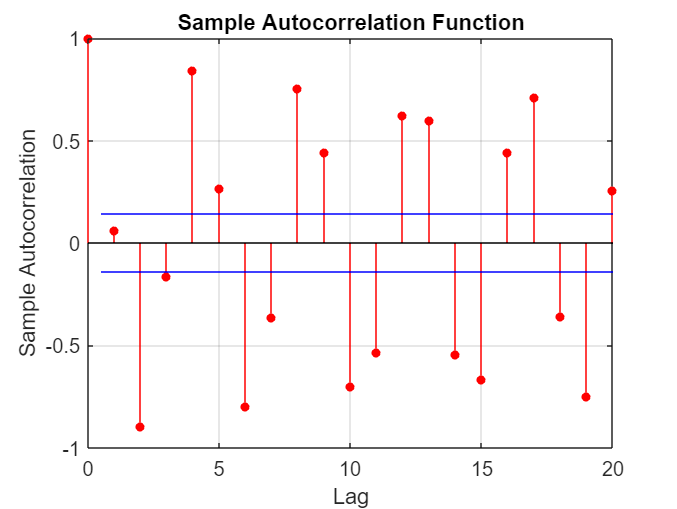

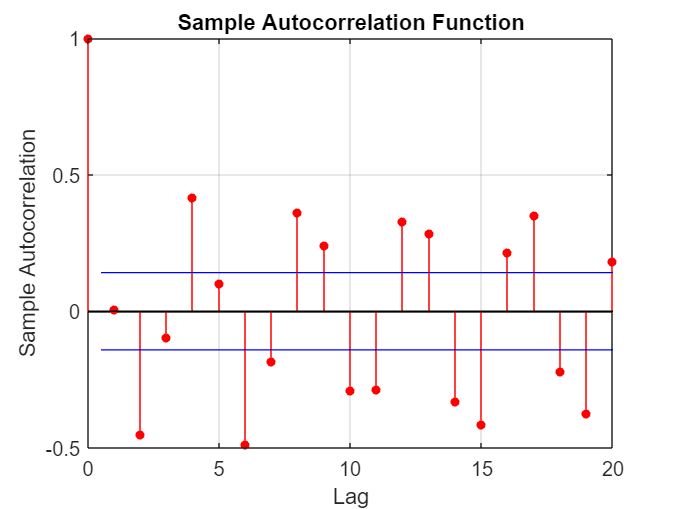

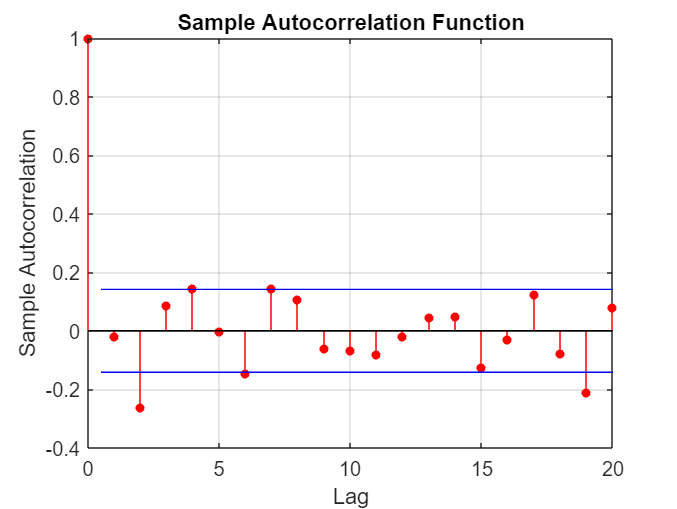

clc;
clear variables;

% Define parameters
A = 1;
f0 = 0.24;
N = 200;
SNR = [20, 10, 1, 0.1]; % Signal to noise ratios

% Generate the signal
t = (0:N-1)'; % Time vector
y = A*sin(2*pi*f0*t); % Signal

% Generate noise and add it to the signal for each SNR
y_noisy = zeros(N, length(SNR));
for i = 1:length(SNR)
    sigma_e = sqrt(var(y)/SNR(i)); % Adjust sigma_e based on SNR
    e = sigma_e * randn(N,1); % Generate noise
    y_noisy(:,i) = y + e; % Add noise to the signal
end

% Compute autocorrelation for each noisy signal
for i = 1:size(y_noisy, 2)
    figure; % Create a new figure window
    autocorr(y_noisy(:,i));
end